# Create a dataset to play with

[⇦ Return to Interpolation](matlab:open('./InterpolationSoln.mlx'))

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output Inline **using the icon   at the top right of the Live Editor pane.

While it is certainly possible to find pre-existing datasets, it is also possible to just create your own. This script walks you through collecting two datasets by selecting points on a graph. 

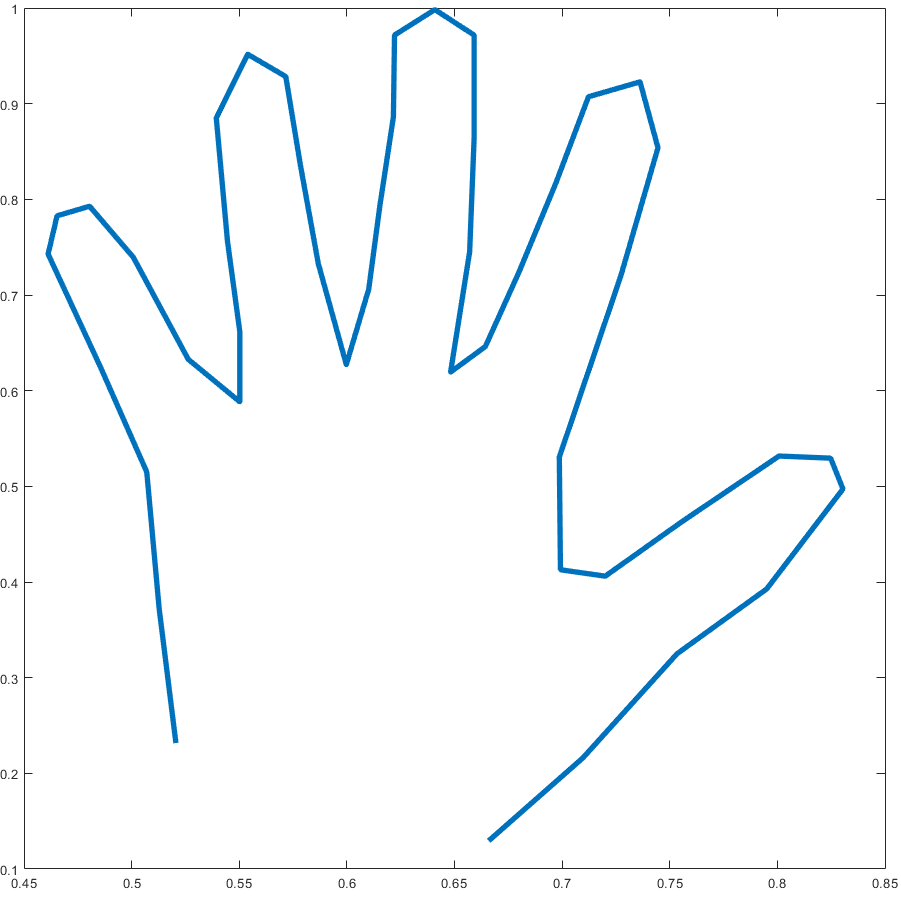            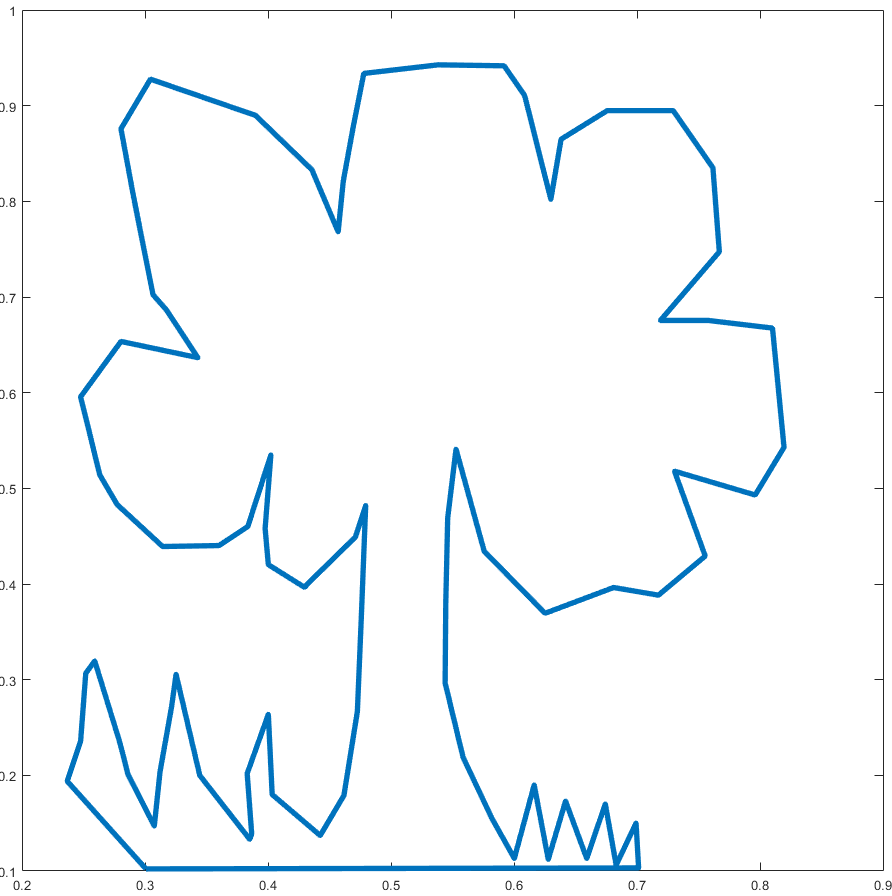

- Trace your hand

- Draw a closed-loop image

[x,y] = CollectData;

#### Check your dataset

Are you satisfied with the result?

% Plot a line connecting each of your points in order
plot(x,y,"*-")

#### Save your dataset

Choose the appropriate label for your dataset and then save. If you create a later dataset that you like more, selecting the same name in the dropdown in this section will overwrite your earlier file. Then go back and repeat this process to save another dataset as `drawing.mat` by setting the dropdown menu appropriately in this section.

% Save the data x and y with the name selected in the dropdown
% in the Data directory
if ~isempty(matlab.project.rootProject)
    % Identify the filepath to the Data folder
    fp = fullfile(currentProject().RootFolder,"Data","testDrawing.mat");
    save(fp,"x","y")
else
    disp("Please load the project before saving this data.")
end

#### Helper functions

function [x,y] = CollectData()
% Load Sample Data
load(fullfile("Data","drawing.mat"),"x","y")
end